**Rede neuronal feedforward  ficheiro START**

**Treino e previsao com os stokes reais dessas linhas**

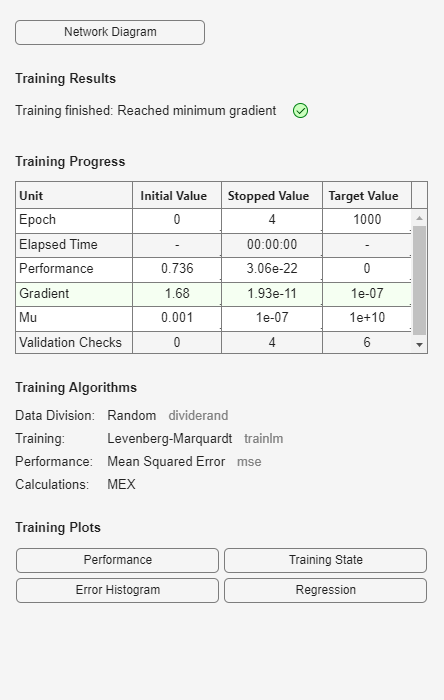

dados_start = readtable('C:\Users\alex-\OneDrive - ISEC\ISEC\ExclusivoDrive\CR\MATLAB-Drive\TrabalhoPratico\Dataset2-Stroke\Start.csv');

X = dados_start{:, 2:end-1}; % entrada: tudo menos o ID e o stroke (input)
y = dados_start.stroke; % saida: stroke (target)

net = feedforwardnet(10); % 10 neurónios

tic;
net = train(net, X', y');

%net.trainFcn = 'trainbfg';
%rede.layers.transferFcn = 'logsig';
tempo_execucao = toc;

%teste com o target original
y_pred = net(X');
%considerar as previsoes em binario para comparar ao stroke ou seja 0.4 = 0 e 0.6 = 1
accuracy = sum(round(y_pred) == y') / numel(y);
erroR = mse (net, y', y_pred);

fprintf('Tempo de Train: %.2f segundos\n', tempo_execucao);

Tempo de Train: 0.84 segundos


fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 60.00%


fprintf('Erro: %.2f%%\n', erroR*100);

Erro: 58.85%
